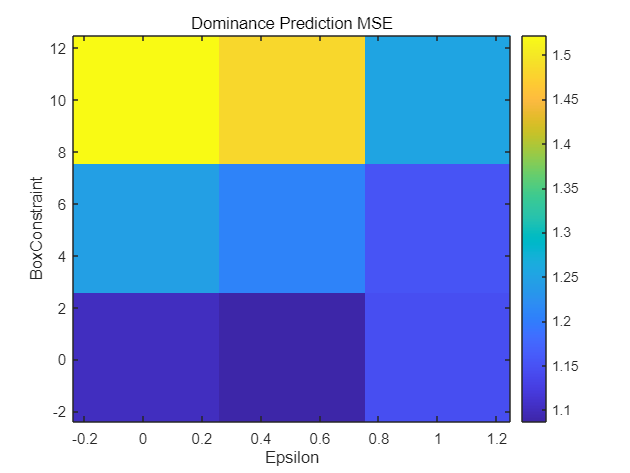

clear all;
clc;

load('1017_preprocessed_filtered_PCA.mat'); 
X = reduced_feature_matrix;  % PCA로 차원 축소된 특징 벡터
y_valence = labels_matrix(:, 1);  % Valence 라벨
y_arousal = labels_matrix(:, 2);  % Arousal 라벨
y_dominance = labels_matrix(:, 3);  % Dominance 라벨

% --- 데이터 분리 (70% 학습, 30% 테스트) ---
cv = cvpartition(size(X, 1), 'HoldOut', 0.3);
trainIdx = training(cv);
testIdx = test(cv);

% --- 학습 데이터와 테스트 데이터 분리 ---
X_train = X(trainIdx, :);
X_test = X(testIdx, :);
y_train_valence = y_valence(trainIdx, :);
y_test_valence = y_valence(testIdx, :);
y_train_arousal = y_arousal(trainIdx, :);
y_test_arousal = y_arousal(testIdx, :);
y_train_dominance = y_dominance(trainIdx, :);
y_test_dominance = y_dominance(testIdx, :);

% --- 하이퍼파라미터 값 설정 ---
box_constraints = [0.1, 1, 10];
epsilons = [0.01, 0.1, 1];

mse_values_valence = zeros(length(box_constraints), length(epsilons));
mse_values_arousal = zeros(length(box_constraints), length(epsilons));
mse_values_dominance = zeros(length(box_constraints), length(epsilons));

% --- 하이퍼파라미터 튜닝 및 MSE 계산 ---
for i = 1:length(box_constraints)
    for j = 1:length(epsilons)
        box = box_constraints(i);
        epsilon = epsilons(j);
        
        % --- SVM 모델 학습 (Valence) ---
        model_valence = fitrsvm(X_train, y_train_valence, 'KernelFunction', 'gaussian', ...
            'BoxConstraint', box, 'Epsilon', epsilon, 'KernelScale', 'auto');
        y_pred_valence = predict(model_valence, X_test);
        mse_values_valence(i, j) = mean((y_pred_valence - y_test_valence).^2);
        
        % --- SVM 모델 학습 (Arousal) ---
        model_arousal = fitrsvm(X_train, y_train_arousal, 'KernelFunction', 'gaussian', ...
            'BoxConstraint', box, 'Epsilon', epsilon, 'KernelScale', 'auto');
        y_pred_arousal = predict(model_arousal, X_test);
        mse_values_arousal(i, j) = mean((y_pred_arousal - y_test_arousal).^2);
        
        % --- SVM 모델 학습 (Dominance) ---
        model_dominance = fitrsvm(X_train, y_train_dominance, 'KernelFunction', 'gaussian', ...
            'BoxConstraint', box, 'Epsilon', epsilon, 'KernelScale', 'auto');
        y_pred_dominance = predict(model_dominance, X_test);
        mse_values_dominance(i, j) = mean((y_pred_dominance - y_test_dominance).^2);
    end
end

cmap = flipud(colormap('parula'));

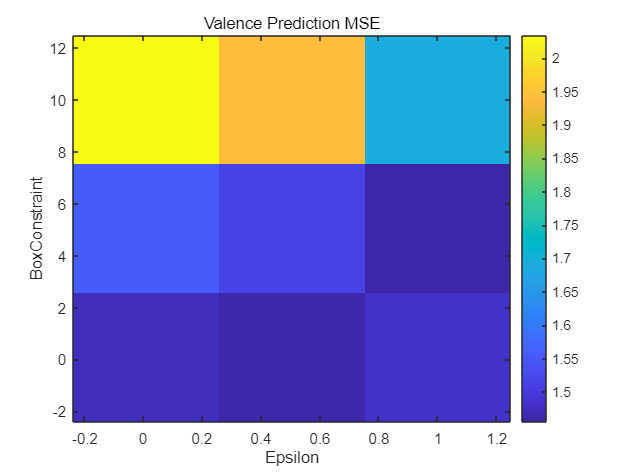


% --- Valence MSE 그래프 그리기 및 저장 ---
figure;
imagesc(epsilons, box_constraints, mse_values_valence);
colorbar;
xlabel('Epsilon');
ylabel('BoxConstraint');
title('Valence Prediction MSE');
set(gca, 'YDir', 'normal');
saveas(gcf, 'SVM_Valence.jpg');

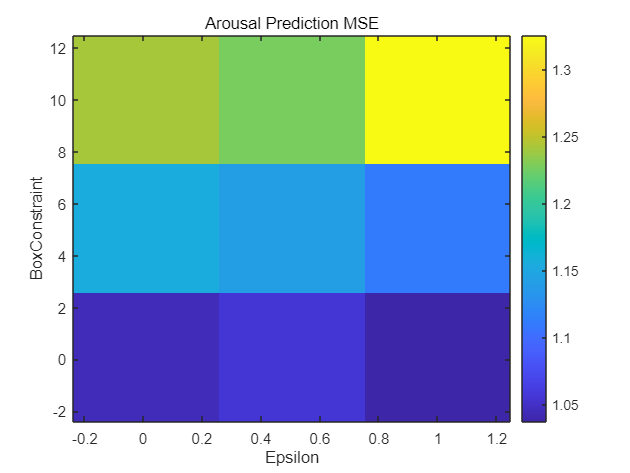


% --- Arousal MSE 그래프 그리기 및 저장 ---
figure;
imagesc(epsilons, box_constraints, mse_values_arousal);
colorbar;
xlabel('Epsilon');
ylabel('BoxConstraint');
title('Arousal Prediction MSE');
set(gca, 'YDir', 'normal');
saveas(gcf, 'SVM_Arousal.jpg');

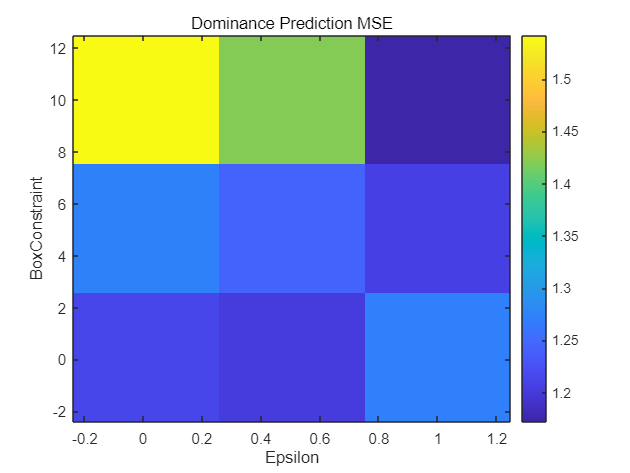


% --- Dominance MSE 그래프 그리기 및 저장 ---
figure;
imagesc(epsilons, box_constraints, mse_values_dominance);
colorbar;
xlabel('Epsilon');
ylabel('BoxConstraint');
title('Dominance Prediction MSE');
set(gca, 'YDir', 'normal');
saveas(gcf, 'SVM_Dominance.jpg');